# Dial Reader Trainer

## Combining Ground Truth Objects

fprintf("<[ DIAL READER TRAINER ]>\n")

<[ DIAL READER TRAINER ]>


fprintf("\nMake Ground Truth Object Array")


Make Ground Truth Object Array

% Select Number of GroundTruth Objects to Combine
prompt = {'How Many GroundTruth Objects do you want to create?:'};
dlgtitle = '# of GroundTruths Selector';
dims = [1 20];
definput = {'1'};
answer = inputdlg(prompt,dlgtitle,dims,definput);

gTruths_num = str2double(answer{1});

% Read Data & Combine Ground Truth Objects into an Array

% For each scene . . .
for i_gt = 1:gTruths_num

%     % Select Folder Containing Image Files
%     [im_folder_path] = uigetdir('','Select a Folder Containing Image Files');
%     
%     % Select Blender Export CSV File
%     [blender_csv_name,path_csv] = uigetfile('*.*', "Select a Vertex Data File");
%     path_and_blender_csv_name = strcat(path_csv, blender_csv_name);
%     
%     % Create GroundTruth from Images & Labels (& store in array)
%     gTruth_array(i) = blender_CSV_Image_2_matlab_GroundTruth(im_folder_path, path_and_blender_csv_name);

   % Select Folder Containing Image Files
    [im_folder_path] = uigetdir('','Select a Folder Containing Image Files');
    
    % Select Blender Export CSV File
    [blender_csv_name,path_csv] = uigetfile('*.*', "Select a Vertex Data File");
    path_and_blender_csv_name = strcat(path_csv, blender_csv_name);
    
%     % Select Blender SKY BBOXES csv File
%     [blender_csv_skyBBOX_name,path_skyBBOX_csv] = uigetfile('*.*', "Select a SKY BBOX Vertex Data File");
%     path_and_blender_skyBBOX_csv_name = strcat(path_skyBBOX_csv, blender_csv_skyBBOX_name);
    
    % Create GroundTruth from Images & Labels
%     gTruth_array(i) = blender_CSV_Image_2_matlab_GroundTruth_choice(im_folder_path, path_and_blender_csv_name, path_and_blender_skyBBOX_csv_name);
    gTruth_array(i_gt) = blender_CSV_Image_2_matlab_GroundTruth_choice(im_folder_path, path_and_blender_csv_name);

end

% % load C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Dial_Reader_TESTS\Photo_Images_Labels.mat
% % load C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Real_Dial_Dataset_Stuff\Real_Dial_Dataset_Labels1_fixed.mat
load C:\BU\Semeter_8_(Spring2023)\Blender\Dial_Reader_Data\Real_Labelled_Data_4-23-2023\Real_Labelled_Data_4-23-2023__SomeAngles.mat
gTruth_array(i_gt+1) = gTruth;

fprintf("\nSetting Stuff Up . . .")


Setting Stuff Up . . .


num_of_images = zeros(2,length(gTruth_array)); % preallocate # of images
for i_gt2 = 1:length(gTruth_array)
    % If the length of the datasource is 1: assume it is an imageDatastore
    source_len = length(gTruth_array(i_gt2).DataSource.Source);
    if (source_len == 1)
        num_of_images(1, i_gt2) = length(gTruth_array(i_gt2).DataSource.Source.Files);
        num_of_images(2, i_gt2) = 1;
    else
        num_of_images(1, i_gt2) = source_len;
        num_of_images(2, i_gt2) = 0;
    end
end

% Preallocate Table: File Name, Data (0-360), Normalized Data
% Normalized Data: 0 to 360 => 0 to 1
dial_table = table('Size',[0,3], 'VariableTypes',{'string','double','double'}, 'VariableNames',{'File','Data','DatN'});
i_bbox_VALID = 0;
old_table_ind = 0;

% mkdir C:\BU\Semeter_8_(Spring2023)\Blender\Dial_Reader_Data cropped_dial_images1

dir_path = 'C:\BU\Semeter_8_(Spring2023)\Blender\Dial_Reader_Data\cropped_dial_images1\';

% Random Color Augmentation Parameters ~ ~ ~ ~ ~ ~ ~ ~ ~ ~
% A: Toggle
% 0 -> Off, 1 -> On
color_aug_toggle = 1;
% B: Fraction Matrix:
% ratio of (0) no augmentation to (1) augmentation
frac_mat = [0,0,1]; 
% C: Length of Fraction Matrix
% # of elements
perc_mat_len = length(frac_mat);

fprintf("\nCreate Table & Write Images . . .")


Create Table & Write Images . . .

warning('off'); % get rid of table warnings

for i_gt3 = 1:i_gt2
    for i_im = 1:num_of_images(1, i_gt3)
        % If it uses an imageDatastore as its source
        if ( num_of_images(2, i_gt3) == 1)
            im_path = gTruth_array(i_gt3).DataSource.Source.Files{i_im};   % Get image file path
        % if not
        else 
             im_path = gTruth_array(i_gt3).DataSource.Source{i_im};        % Get image file path
        end
        im = imread(im_path);                                       % read image into variable
        [~, im_filename, ~] = fileparts(im_path);                   % get image file name
        num_of_bboxes = length(gTruth_array(i_gt3).LabelData.Dial{i_im});  % Find # of bounding boxes
        [im_h, im_w, ~] = size(im);                                 % height & width of image
        % For Each Bounding Box . . .
        for i_bbox = 1:num_of_bboxes
            bbox = gTruth_array(i_gt3).LabelData.Dial{i_im}(i_bbox).Position;      % get each bounding box
            [tl_w, tl_h, br_w, br_h] = check_bbox_bounds(bbox, im_w, im_h); % check if the bounding box is within frame
            % If the bounding box is within the bounds of the image . . .
            if ( (tl_w && tl_h) && (br_w && br_h) )
                needle_angle = gTruth_array(i_gt3).LabelData.Dial{i_im}(i_bbox).Pointer_Angle; % get needle angle
                % If there is a labelled needle angle . . .
                if ~isempty(needle_angle)
                    i_bbox_VALID = i_bbox_VALID + 1;    % increment count of valid bounding boxes for this image
                    im_bbox = im(bbox(2):(bbox(2)+bbox(4)), bbox(1):(bbox(1)+bbox(3)), :);  % cut out bounding box area from image
                    im_bbox_name = sprintf('%s__%d.png', im_filename, i_bbox_VALID);        % create name for new image
                    im_bbox_path = strcat('C:\BU\Semeter_8_(Spring2023)\Blender\Dial_Reader_Data\cropped_dial_images1\', im_bbox_name); % create image file path
                    imwrite(im_bbox, im_bbox_path);                                         % write image to file
                    dial_table.File(old_table_ind + i_bbox_VALID) = im_bbox_path;           % add new image file path to table
                    dial_table.Data(old_table_ind + i_bbox_VALID) = needle_angle;           % add needle angle to table
                    dial_table.DatN(old_table_ind + i_bbox_VALID) = needle_angle / 360; % add normalized needle angle to table
                    
                    % Randomly Add Color Augmented Image
                    if (frac_mat(randi(perc_mat_len)) && color_aug_toggle)
                        i_bbox_VALID = i_bbox_VALID + 1;    % increment count of valid bounding boxes for this image
                        im_bbox_aug = jitterColorHSV(im_bbox,Hue=[-0.3 0.3], Saturation=[-0.3 0.3], Brightness=[-0.1 0.3]);
                        im_bbox_aug_path = sprintf("%s%s__aug__%d.png", dir_path, im_filename, i_bbox_VALID); % create image file path
                        imwrite(im_bbox_aug, im_bbox_aug_path);
                        dial_table.File(old_table_ind + i_bbox_VALID) = im_bbox_aug_path;       % add new image file path to table
                        dial_table.Data(old_table_ind + i_bbox_VALID) = needle_angle;           % add needle angle to table
                        dial_table.DatN(old_table_ind + i_bbox_VALID) = needle_angle / 360;     % add normalized needle angle to table
                    end
                end
            end
    
        end
        old_table_ind = i_bbox_VALID + old_table_ind;   % set the current # of rows in the table
        i_bbox_VALID = 0;   % reset count of valid bounding boxes
    end
end

warning('on'); % turn warnings back on for later code

% Validation Data ~ ~ ~ ~ ~ ~ ~ ~ ~ ~
fprintf("\nCreate Validation Table & Write Images . . .")


Create Validation Table & Write Images . . .

warning('off'); % get rid of table warnings

load C:\BU\Semeter_8_(Spring2023)\Deep_Learning_Training\Videos_from_YouTube\Test_Data_Youtube1_Labels1.mat
num_valid_ims = length(gTruth.DataSource.Source);

valid_table = table('Size',[0,3], 'VariableTypes',{'string','double','double'}, 'VariableNames',{'File','Data','DatN'});

% Reset
i_bbox_VALID = 0;
old_table_ind = 0;

for i_im = 1:num_valid_ims
    im_path = gTruth.DataSource.Source{i_im};           % Get image file path
    im = imread(im_path);                               % read image into variable
    [~, im_filename, ~] = fileparts(im_path);           % get image file name
    num_of_bboxes = length(gTruth.LabelData.Dial{i_im});% Find # of bounding boxes
    [im_h, im_w, ~] = size(im);                         % height & width of image
    % For Each Bounding Box . . .
    for i_bbox = 1:num_of_bboxes
        bbox = gTruth.LabelData.Dial{i_im}(i_bbox).Position;      % get each bounding box
        [tl_w, tl_h, br_w, br_h] = check_bbox_bounds(bbox, im_w, im_h); % check if the bounding box is within frame
        % If the bounding box is within the bounds of the image . . .
        if ( (tl_w && tl_h) && (br_w && br_h) )
            needle_angle = gTruth.LabelData.Dial{i_im}(i_bbox).Pointer_Angle; % get needle angle
            % If there is a labelled needle angle . . .
            if ~isempty(needle_angle)
                i_bbox_VALID = i_bbox_VALID + 1;    % increment count of valid bounding boxes for this image
                im_bbox = im(bbox(2):(bbox(2)+bbox(4)), bbox(1):(bbox(1)+bbox(3)), :);  % cut out bounding box area from image
                im_bbox_name = sprintf('%s__%d.png', im_filename, i_bbox_VALID);        % create name for new image
                im_bbox_path = strcat('C:\BU\Semeter_8_(Spring2023)\Blender\Dial_Reader_Data\valid1\', im_bbox_name); % create image file path
                imwrite(im_bbox, im_bbox_path);                                         % write image to file
                valid_table.File(old_table_ind + i_bbox_VALID) = im_bbox_path;           % add new image file path to table
                valid_table.Data(old_table_ind + i_bbox_VALID) = needle_angle;           % add needle angle to table
                valid_table.DatN(old_table_ind + i_bbox_VALID) = needle_angle / 360;     % add normalized needle angle to table
            end
        end
    end
    old_table_ind = i_bbox_VALID + old_table_ind;   % set the current # of rows in the table
    i_bbox_VALID = 0;   % reset count of valid bounding boxes
end
warning('on'); % turn warnings back on for later code

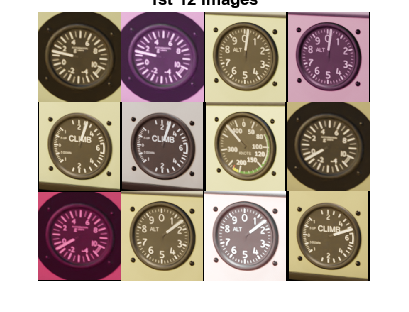

% Display 1st 12 cutout images
montage(dial_table.File(1:12))
title("1st 12 Images")

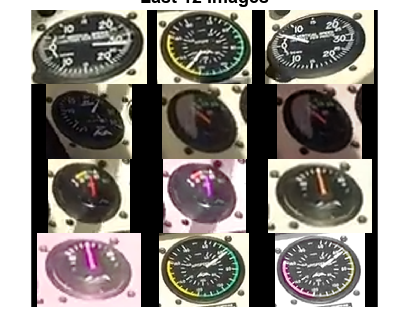

% dial_table.DatN(1:12)

% Display last 12 cutout images
montage(dial_table.File(end-11:end))
title("Last 12 Images")

% dial_table.DatN(end-9:end)

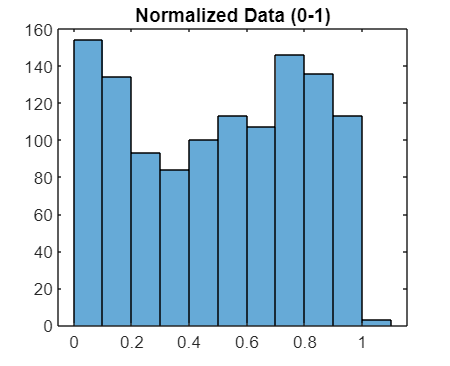

% Histogram
histogram(dial_table.DatN)
title("Normalized Data (0-1)")

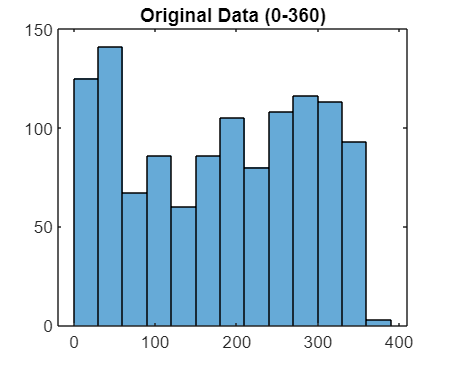

histogram(dial_table.Data)
title("Original Data (0-360)")

% Resize Images
new_size = 256;
train_data = augmentedImageDatastore([new_size new_size], dial_table(:,[1,3]))

train_data =   augmentedImageDatastore with properties:

         NumObservations: 1183
           MiniBatchSize: 1
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [256 256]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


% Resize Validation Images
valid_data = augmentedImageDatastore([new_size new_size], valid_table(:,[1,3]))

valid_data =   augmentedImageDatastore with properties:

         NumObservations: 66
           MiniBatchSize: 1
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [256 256]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


% Set Training Options
net_options = trainingOptions("sgdm", ...
    "Plots","training-progress", ...
    "MaxEpochs",30, ...
    "Shuffle","every-epoch", ...
    "InitialLearnRate",0.001, ...
    "MiniBatchSize",64, ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropPeriod", 10, ...
    "ValidationData", valid_data, ...
    "ValidationFrequency",15)

net_options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 40
                   MiniBatchSize: 64
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 15
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: [


% Create Network Architecture
% lgraph = create_cnn_lgraph_reg(1)
lgraph = create_cnn_lgraph_reg_DarkNet53_1(1)

lgraph =   LayerGraph with properties:

         Layers: [184×1 nnet.cnn.layer.Layer]
    Connections: [206×2 table]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}



% Keeps Warning on
warning('on','nnet_cnn:warning:GPULowOnMemory');

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:30 |         1.85 |         1.34 |       1.7114 |       0.9027 |          0.0010 |
|       1 |          15 |       00:04:47 |         1.94 |         1.43 |       1.8854 |       1.0222 |          0.0010 |
|       2 |          30 |       00:10:40 |         0.67 |         0.70 |       0.2271 |       0.2477 |          0.0010 |
|       3 |          45 |       00:16:31 |         0.34 |         0.61 |       0.0561 |       0.1838 |          0.0010 |
|       3 |          50 |       00:18:27 |         0.31 |              |       0.0486 |              |          0.0010 |
|       4 |          60 |       00:22:20 |         0.34 |         0.48 |       0.0586 |       0.1137 |          0.0010 |
|       5 |          75 |       00:28:12 |         0.22 |         0.44 |       0.0233 |       0.0984 |          0.0010 |
|       5 |          90 |       00:34:01 |         0.23 |         0.64 |       0.0270 |       0.2070 |          0.0010 |
|       6 |         100 |       

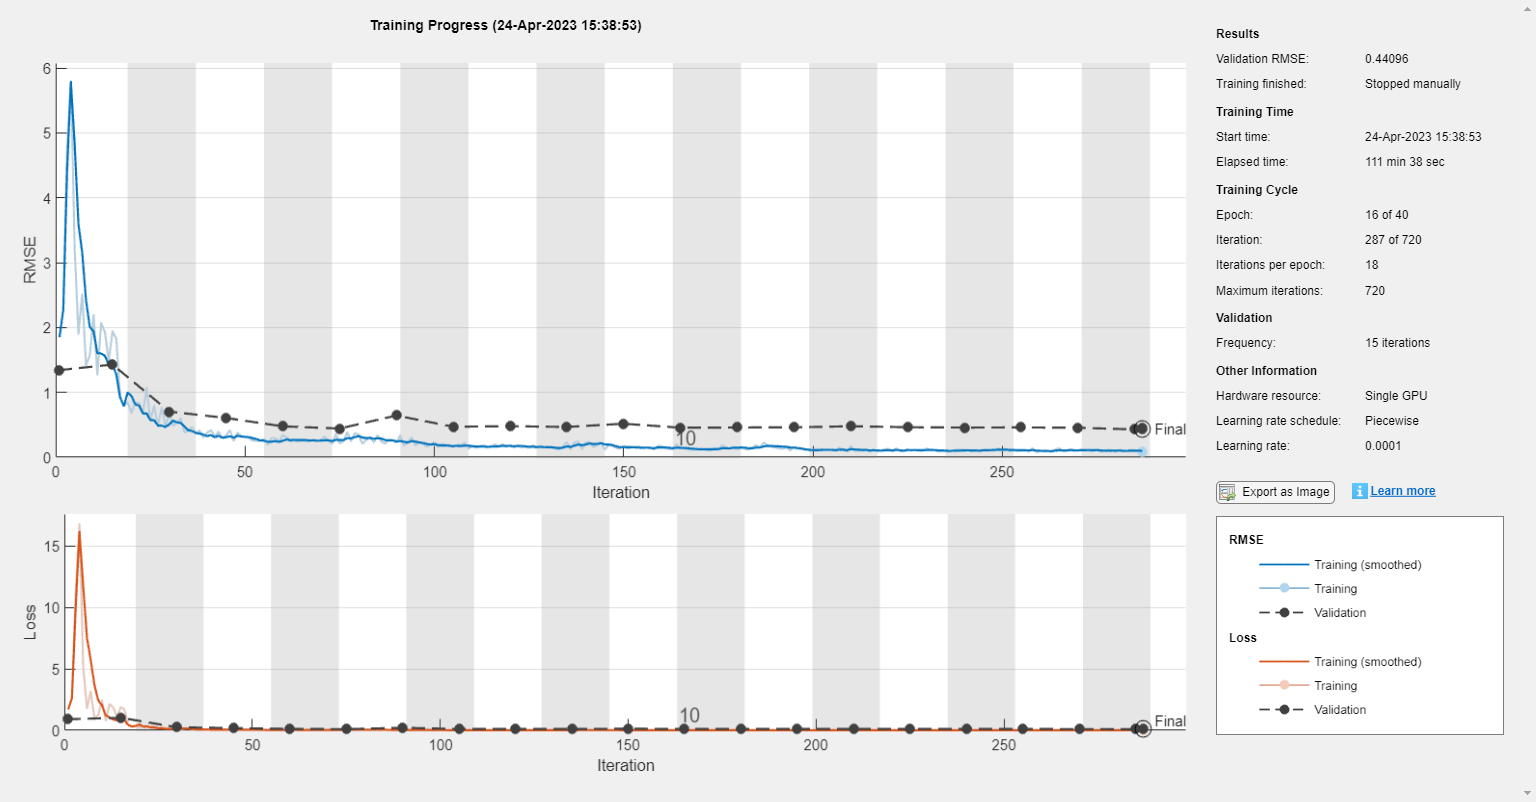

dialAngleNet =   DAGNetwork with properties:

         Layers: [184×1 nnet.cnn.layer.Layer]
    Connections: [206×2 table]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


% Train Convolution Neural Network
dialAngleNet = trainNetwork(train_data, lgraph, net_options)

% dialAngleNet = trainNetwork(train_data, lgraph_1, net_options)


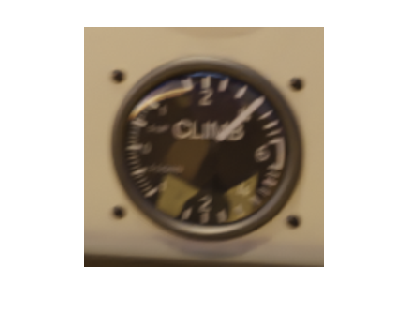

test_im_index = 900;
test_im_og = imread(dial_table.File{test_im_index});
test_im = imresize(test_im_og, [new_size new_size]);
imshow(test_im)

pred_ang = (predict(dialAngleNet, test_im) * 360)

pred_ang = single
61.2222

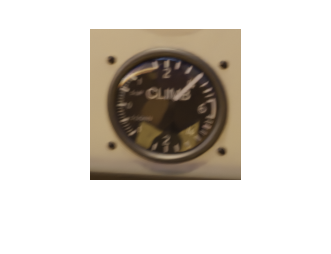

imshow(test_im_og)

real_ang = dial_table.Data(test_im_index)

real_ang = 44

## Results

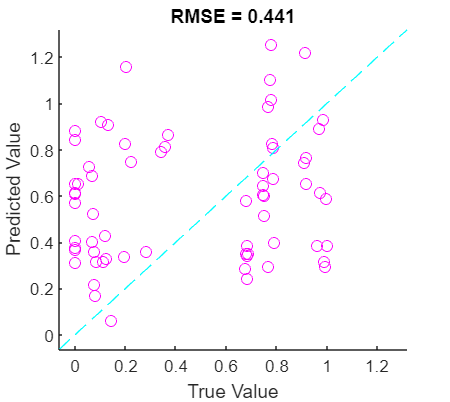

% True & Predicted Angles
ang_pred = predict(dialAngleNet,valid_data);
ang_true = valid_table.DatN;
% Error
pred_error = ang_true - ang_pred;
% RMSE (Root-Mean-Squared-Error)
rmse = sqrt(mean(pred_error .^ 2));

% Plot Predicted vs. True Value
scatter(ang_true, ang_pred, 'm o')
xlabel("True Value")
ylabel("Predicted Value")
title(sprintf("RMSE = %.3f", rmse))
hold on
UpBound = max(max(ang_true), max(ang_pred));
LowBound = min(min(ang_true), min(ang_pred));
extra_space = 0.05 * (UpBound - LowBound);
UpBound = UpBound + extra_space;
LowBound = LowBound - extra_space;
plot([LowBound UpBound], [LowBound UpBound],'c--')
axis([LowBound UpBound LowBound UpBound])
hold off

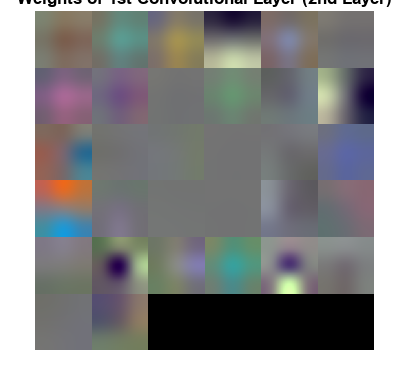

% All Weights
weights = dialAngleNet.Layers(2).Weights;
montage(rescale(weights))
title("Weights of 1st Convolutional Layer (2nd Layer)")

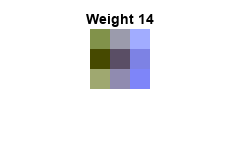


% Weight A
w_A =14;
imshow(rescale(weights(:,:,:,w_A)), 'InitialMagnification', 2000)
title(sprintf("Weight %d", w_A))

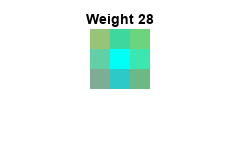


% Weight B
w_B = 28;
imshow(rescale(weights(:,:,:,w_B)), 'InitialMagnification', 2000)
title(sprintf("Weight %d", w_B))

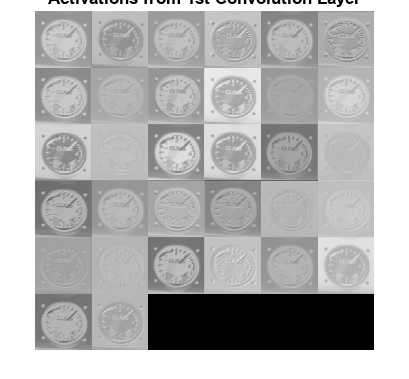

% 1st Activation
actvn = dialAngleNet.activations(test_im,"conv3");

% Last Activation
actvn5 = activations(dialAngleNet, im, "res23");

% Activations from 1st Convolution Layer
montage(mat2gray(actvn))    % mat2gray() normalizes the images
title("Activations from 1st Convolution Layer")

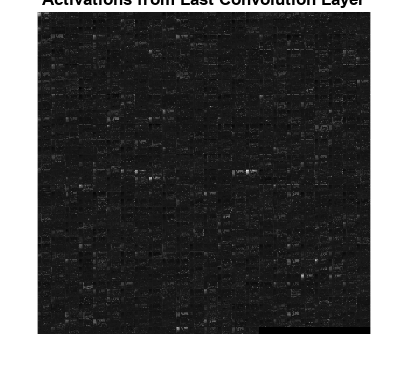


% Activations from Last Convolution Layer
montage(mat2gray(actvn5))   % mat2gray() normalizes the images
title("Activations from Last Convolution Layer")

function [top_L_w, top_L_h, bottom_R_w, bottom_R_h] = check_bbox_bounds(bbox_vec, f_width, f_height)
    %{
      If the bounding box is in the frame all of the 
      output variables will equal 1 (True)
    %}

    % Discard bounding boxes outside the frame
    top_L_w = ((bbox_vec(1) < f_width) & (bbox_vec(1) > 0));   % top left width check
    top_L_h = ((bbox_vec(2) < f_height) & (bbox_vec(2) > 0));  % top left height check
    bottom_R_w = (( bbox_vec(1) + bbox_vec(3) ) < f_width) & (( bbox_vec(1) + bbox_vec(3) ) > 0); % bottom right width check
    bottom_R_h = (( bbox_vec(2) + bbox_vec(4) ) < f_height) & (( bbox_vec(2) + bbox_vec(4) ) > 0);% bottom right height check);
end